Question 3.5

See the code for an alternative stopping criterion also based on convergence properties. However, the graph for this criterion is quite uninformative (fluctuates a lot and tends toward 0 very erratically)

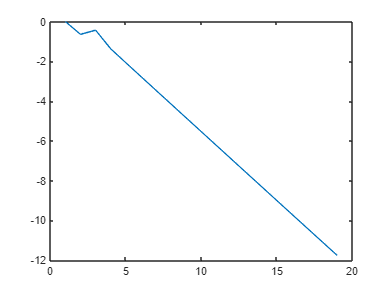

%a)

[a b] = hwk2p3([1 1], 3);
x_a = a;
err_a = hwk2p3_err([1 1], 3);
tr_err_a = norm(x_a);
plot(1:length(err_a), log(err_a))



%b)

[a b] = hwk2p3([-1 1], 3);
x_b = a;
err_b = hwk2p3_err([-1 1], 3);
tr_err_b = norm(x_b);
plot(1:length(err_b), log(err_b))



%c)

[a b] = hwk2p3([-1 -1], 3);
x_c = a;
err_c = hwk2p3_err([-1 -1], 3);
tr_err_c = norm(x_c);
plot(1:length(err_c), log(err_c))


%d)

[a b] = hwk2p3([1 -1], 3);
x_d = a;
err_d = hwk2p3_err([1 -1], 3);
tr_err_d = norm(x_d);
plot(1:length(err_d), log(err_d))

We expect Q-linear or R-linear convergence of grad(f). This can be seen in the graph. 

Question 3.6

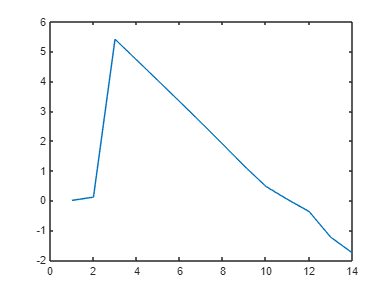

%a)

[a b] = hwk2p3([1 1], 1000);
x_a = a;
err_a = hwk2p3_err([1 1], 1000);
tr_err_a = norm(x_a);
plot(1:length(err_a), log(err_a))


%b)

[a b] = hwk2p3([-1 1], 1000);
x_b = a;
err_b = hwk2p3_err([-1 1], 1000);
tr_err_b = norm(x_b);
plot(1:length(err_b), log(err_b))


%c)

[a b] = hwk2p3([-1 -1], 1000);
x_c = a;
err_c = hwk2p3_err([-1 -1], 1000);
tr_err_c = norm(x_c);
plot(1:length(err_c), log(err_c))


%d)

[a b] = hwk2p3([1 -1], 1000);
x_d = a;
err_d = hwk2p3_err([1 -1], 1000);
tr_err_d = norm(x_d);
plot(1:length(err_d), log(err_d))

Note: the sharp drop at the start of the graphs should be ignored as we initialised the error at 1 in our algorith. 

We expect Q-linear or R-linear convergence of grad(f). This can be seen in the graph. 

hwk2p3 function that outputs error vector:

function [err_vec] = hwk2p3_err(x0, c)
 %Q = [1 0; 0 c];
    err = 1;
    err_vec = [1];
    eps = 1e-5; %chose an epsilon that allowed very close convregence
                %while still allowing stopping due to convergence criterion 
                %(as opposed to 1000 steps)
    steps = 1;
    k =0.5;
    alpha = 1;
    rho = 0.5; %backstepping parameter
  
    while err > eps
       % fn = dot(x0, Q*x0);
        d = grad(x0, c); % derivative
        p = -d/norm(d); %direction of search
       
        xn = x0 + alpha*p;
        %fnk = dot(xn, Q*xn);
    
        %backtrack armijio
        while fn(xn, c) > fn(x0, c) + k*alpha*dot(d, p)
            alpha = rho*alpha;
            A_k0 = norm(grad(xn, c));
            xn = x0 + alpha*p;
            A_k1 = norm(grad(x0 + alpha*p, c));
            %fnk = dot(xn, Q*xn);
            %err = abs(A_k1/A_k0 - 1); Alternative!
            err = abs(A_k1);
            err_vec(end+1) = err;
            
        end
        if err <= eps
            if fn(xn, c) >= fn(x0, c)
               xn  =  x0;
            end
            break
        end
        
        steps = steps + 1;
        if steps >= 1000
            break
        end
        x0 = xn;
        
    end
    xn = x0;
    err = err;
end